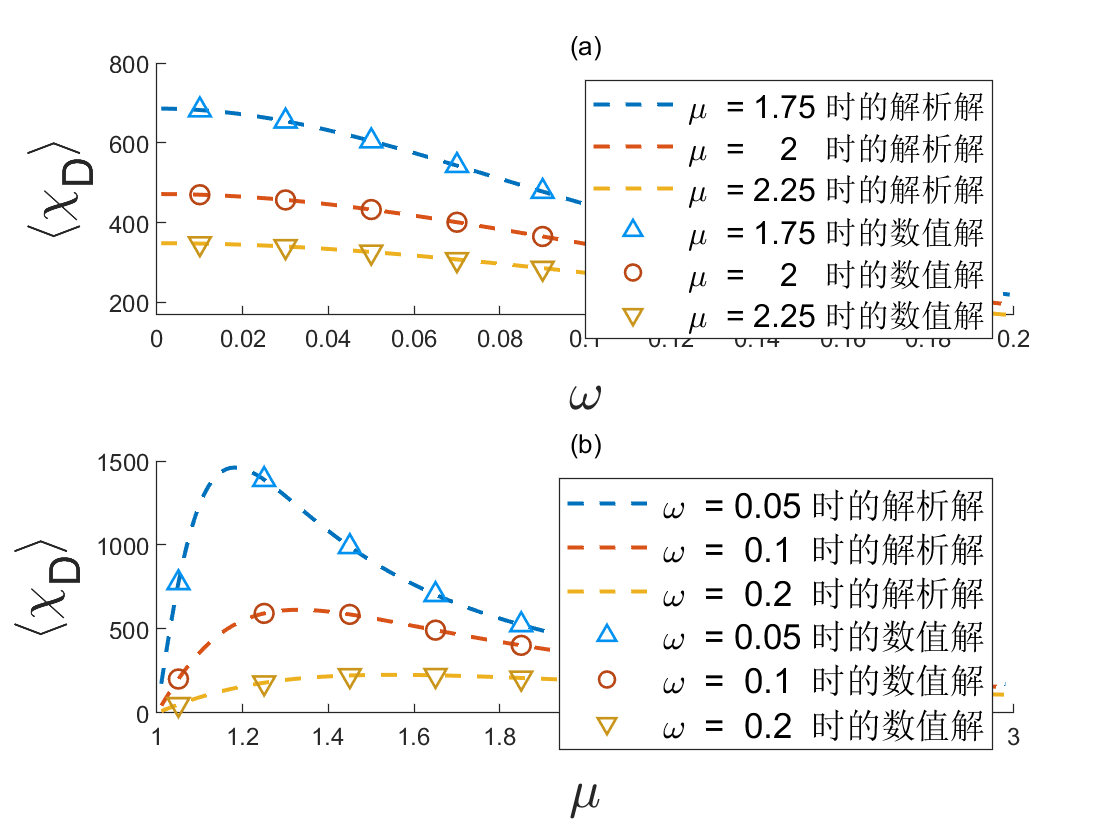

way1 = 'D:/Code/C/level2/work3/fig2.bin';


fileID1=fopen(way1,'r');


A = fread(fileID1,[2 inf],'double');

fclose(fileID1);


figure;
subplot(2,1,1)
title('(a)')
hold on;
for i=0:2
    plot(A(1,1+i*200:200*i+199),A(2,1+i*200:199+i*200),"--","LineWidth",1.5)
end
scatter(A(1,1201:1210),A(2,1201:1210),50,"^","MarkerEdgeColor",[0,114,189]/200,"LineWidth",1)
scatter(A(1,1201+10:1210+10),A(2,1201+10:1210+10),50,"o","MarkerEdgeColor",[217,83,25]/300,"LineWidth",1)
scatter(A(1,1201+20:1210+20),A(2,1201+20:1210+20),50,"v","MarkerEdgeColor",[237,177,32]/300,"LineWidth",1)

legend(strcat(" \mu  = ",num2str(A(1,200))," 时的解析解"), ...
    strcat(" \mu  =    ",num2str(A(1,400)),"   时的解析解"), ...
    strcat(" \mu  = ",num2str(A(1,600))," 时的解析解"), ...
    strcat(" \mu  = ",num2str(A(1,200))," 时的数值解"), ...
    strcat(" \mu  =    ",num2str(A(1,400)),"   时的数值解"), ...
    strcat(" \mu  = ",num2str(A(1,600))," 时的数值解"), ...
    "FontSize",12)
xlabel("\omega","FontSize",20)
ylabel("\langle\chi_D\rangle","FontSize",20)
hold off

subplot(2,1,2)
title('(b)');
hold on;
for i=3:5
    plot(A(1,1+i*200:200*i+199),A(2,1+i*200:199+i*200),"--","LineWidth",1.5)
end
scatter(A(1,1231:1240),A(2,1231:1240),50,"^","MarkerEdgeColor",[0,114,189]/200,"LineWidth",1)
scatter(A(1,1231+10:1240+10),A(2,1231+10:1240+10),50,"o","MarkerEdgeColor",[217,83,25]/300,"LineWidth",1)
scatter(A(1,1231+20:1240+20),A(2,1231+20:1240+20),50,"v","MarkerEdgeColor",[237,177,32]/300,"LineWidth",1)

legend(strcat(" \omega  = ",num2str(A(1,800))," 时的解析解"), ...
    strcat(" \omega  =  ",num2str(A(1,1000)),"  时的解析解"), ...
    strcat(" \omega  =  ",num2str(A(1,1200)),"  时的解析解"), ...
    strcat(" \omega  = ",num2str(A(1,800))," 时的数值解"), ...
    strcat(" \omega  =  ",num2str(A(1,1000)),"  时的数值解"), ...
    strcat(" \omega  =  ",num2str(A(1,1200)),"  时的数值解"), ...
    "FontSize",13)
xlabel("\mu","FontSize",20)
ylabel("\langle\chi_D\rangle","FontSize",20)
hold off